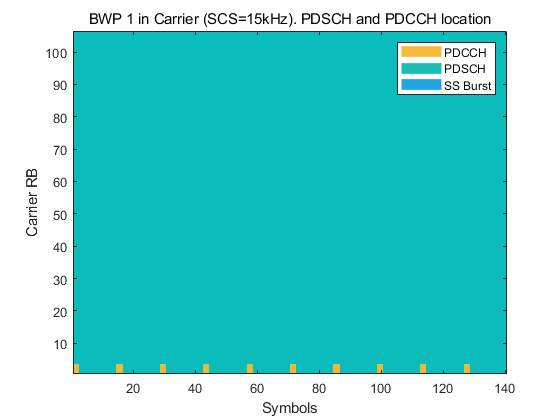

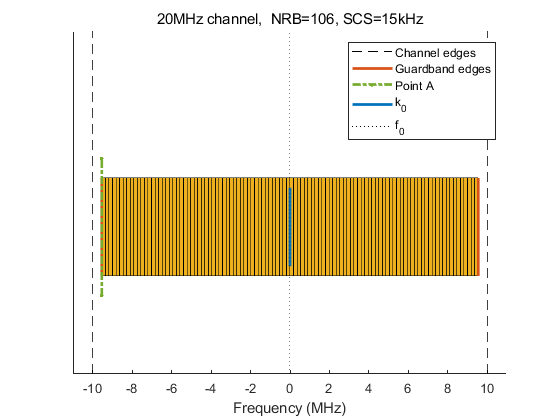

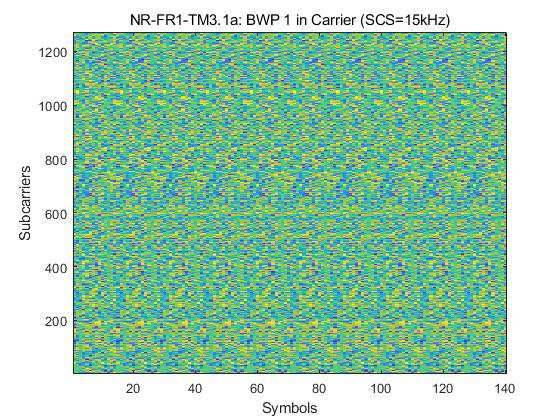

clear;
% Select the NR-TM waveform parameters
nrtm = "NR-FR1-TM3.1a";  % NR-TM name and properties
bw   = "20MHz";  % Channel bandwidth
scs  = "15kHz";  % Subcarrier spacing
dm   = "FDD";  % Duplexing mode

% Create generator object for the above NR-TM
tmWaveGen = hNRReferenceWaveformGenerator(nrtm,bw,scs,dm);

% Ensure no windowing to highlight impact of filtering on ACLR
tmWaveGen = makeConfigWritable(tmWaveGen);
tmWaveGen.Config.WindowingPercent = 0;    

% Generate waveform
[tmWaveform,tmWaveInfo] = generateWaveform(tmWaveGen);
samplingRate = tmWaveInfo.Info.SamplingRate;   % Waveform sampling rate (Hz)

% Visualize the associated PRB and subcarrier resource grids
displayResourceGrid(tmWaveGen);

 RMS EVM, Peak EVM, slot 0: 0.000 0.000%
 RMS EVM, Peak EVM, slot 1: 0.000 0.000%
 RMS EVM, Peak EVM, slot 2: 0.000 0.000%
 RMS EVM, Peak EVM, slot 3: 0.000 0.000%
 RMS EVM, Peak EVM, slot 4: 0.000 0.000%
 RMS EVM, Peak EVM, slot 5: 0.000 0.000%
 RMS EVM, Peak EVM, slot 6: 0.000 0.000%
 RMS EVM, Peak EVM, slot 7: 0.000 0.000%
 RMS EVM, Peak EVM, slot 8: 0.000 0.000%
 RMS EVM, Peak EVM, slot 9: 0.000 0.000%
Averaged RMS EVM frame 0: 0.000%


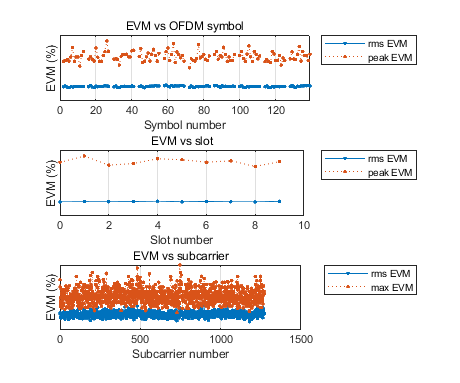

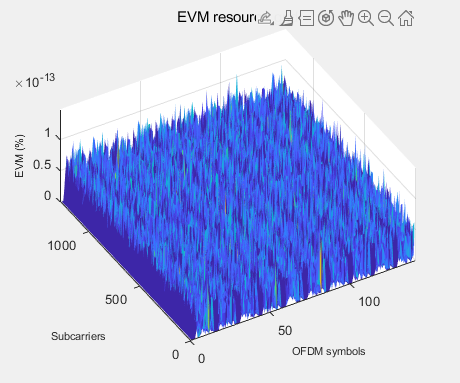

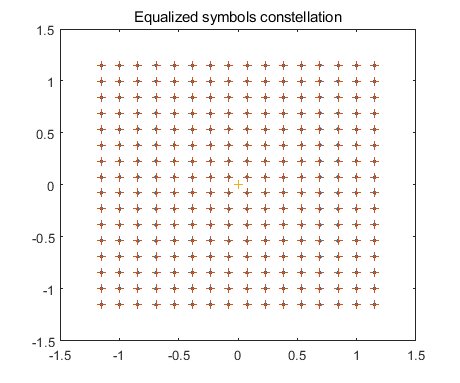

Averaged overall RMS EVM: 0.000%
Overall Peak EVM = 1.3518e-13%


evmInfo = 包含以下字段的 struct :
     SubcarrierRMS: [1272×1 double]
    SubcarrierPeak: [1272×1 double]
         SymbolRMS: [140×1 double]
        SymbolPeak: [140×1 double]
           SlotRMS: [10×1 double]
          SlotPeak: [10×1 double]
           EVMGrid: [1272×140 double]
        OverallEVM: [1×1 struct]



% EVM configuration parameters  
evmCfg.PlotEVM = true;
% evmCfg.SampleRate = samplingRate;
evmCfg.Label = tmWaveGen.ConfiguredModel{1};

% Measure the EVM related statistics for the transmitted waveform without filtering
evmInfo = hNRPDSCHEVM(tmWaveGen.Config,tmWaveform,evmCfg)

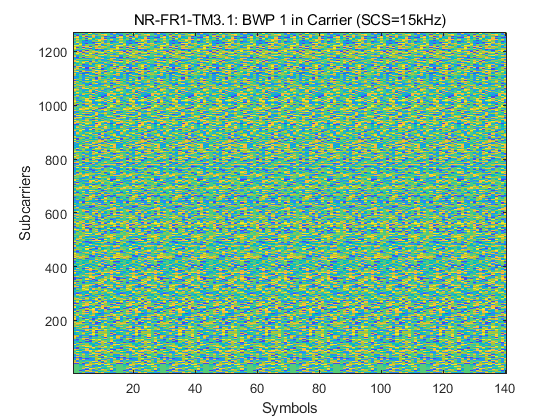

clear;
% Select the NR-TM waveform parameters
nrtm = "NR-FR1-TM3.1";  % NR-TM name and properties
bw   = "20MHz";  % Channel bandwidth
scs  = "15kHz";  % Subcarrier spacing
dm   = "FDD";  % Duplexing mode

% Create generator object for the above NR-TM
tmWaveGen = hNRReferenceWaveformGenerator(nrtm,bw,scs,dm);

% Ensure no windowing to highlight impact of filtering on ACLR
tmWaveGen = makeConfigWritable(tmWaveGen);
tmWaveGen.Config.WindowingPercent = 0;    

% Generate waveform
[tmWaveform,tmWaveInfo] = generateWaveform(tmWaveGen);
samplingRate = tmWaveInfo.Info.SamplingRate;   % Waveform sampling rate (Hz)

% Visualize the associated PRB and subcarrier resource grids
displayResourceGrid(tmWaveGen);

aclrParameters = hACLRParametersNR(tmWaveGen.Config);
disp(aclrParameters);

            Bandwidth: 20000000
    SubcarrierSpacing: 15000
      BandwidthConfig: 19080000
        BandwidthACLR: 100000000
                  OSR: 4
         SamplingRate: 122880000



 RMS EVM, Peak EVM, slot 0: 0.000 0.000%
 RMS EVM, Peak EVM, slot 1: 0.000 0.000%
 RMS EVM, Peak EVM, slot 2: 0.000 0.000%
 RMS EVM, Peak EVM, slot 3: 0.000 0.000%
 RMS EVM, Peak EVM, slot 4: 0.000 0.000%
 RMS EVM, Peak EVM, slot 5: 0.000 0.000%
 RMS EVM, Peak EVM, slot 6: 0.000 0.000%
 RMS EVM, Peak EVM, slot 7: 0.000 0.000%
 RMS EVM, Peak EVM, slot 8: 0.000 0.000%
 RMS EVM, Peak EVM, slot 9: 0.000 0.000%
Averaged RMS EVM frame 0: 0.000%


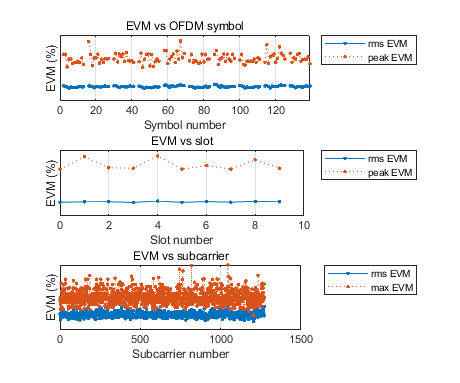

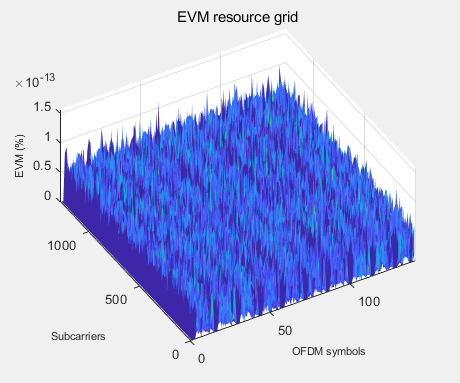

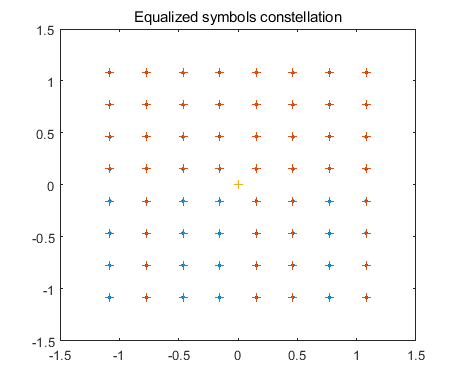

Averaged overall RMS EVM: 0.000%
Overall Peak EVM = 1.4257e-13%



% Design filter
lpFilt = designfilt('lowpassfir',...
    'PassbandFrequency',aclrParameters.BandwidthConfig/2,...
    'StopbandFrequency',aclrParameters.Bandwidth/2,...
    'PassbandRipple',0.1,...
    'StopbandAttenuation',80,...
    'SampleRate',samplingRate);

% Apply filter
filtTmWaveform = filter(lpFilt,tmWaveform);

% Apply required oversampling
resampled = resample(tmWaveform,aclrParameters.OSR,1);           % Not filtered
filtResampled = resample(filtTmWaveform,aclrParameters.OSR,1);   % Filtered

% Create and configure a memoryless nonlinearity to model the amplifier
nonLinearity = comm.MemorylessNonlinearity;
nonLinearity.Method = 'Rapp model';
nonLinearity.Smoothness = 3;              % p parameter          
nonLinearity.LinearGain = 0.5;            % dB
nonLinearity.OutputSaturationLevel = 2;   % It limits the output signal level  

% Signal conditioning to control the HPA input back-off level
resampled = resampled/max(abs(resampled));                % Not filtered
filtResampled = filtResampled/max(abs(filtResampled));    % Filtered

% Apply the amplifier model to the NR waveforms
txWaveform = nonLinearity(resampled);           % Not filtered
txFiltWaveform = nonLinearity(filtResampled);   % Filtered

% Apply required oversampling
txWaveform = resample(txWaveform,1,aclrParameters.OSR);           % Not filtered
txFiltWaveform = resample(txFiltWaveform,1,aclrParameters.OSR);   % Filtered

% EVM configuration parameters  
evmCfg.PlotEVM = true;
% evmCfg.SampleRate = samplingRate;
evmCfg.Label = tmWaveGen.ConfiguredModel{1};

% % Measure the EVM related statistics for the transmitted waveform without filtering
% evmInfo = hNRPDSCHEVM(tmWaveGen.Config,txWaveform,evmCfg);
% evmFilterInfo = hNRPDSCHEVM(tmWaveGen.Config,txFiltWaveform,evmCfg);

% Measure the EVM related statistics for the transmitted waveform without filtering
evmInfo = hNRPDSCHEVM(tmWaveGen.Config,tmWaveform,evmCfg);

 RMS EVM, Peak EVM, slot 0: 0.115 0.940%
 RMS EVM, Peak EVM, slot 1: 0.116 0.793%
 RMS EVM, Peak EVM, slot 2: 0.117 0.831%
 RMS EVM, Peak EVM, slot 3: 0.117 1.242%
 RMS EVM, Peak EVM, slot 4: 0.114 0.842%
 RMS EVM, Peak EVM, slot 5: 0.112 0.779%
 RMS EVM, Peak EVM, slot 6: 0.112 0.715%
 RMS EVM, Peak EVM, slot 7: 0.116 0.863%
 RMS EVM, Peak EVM, slot 8: 0.116 0.916%


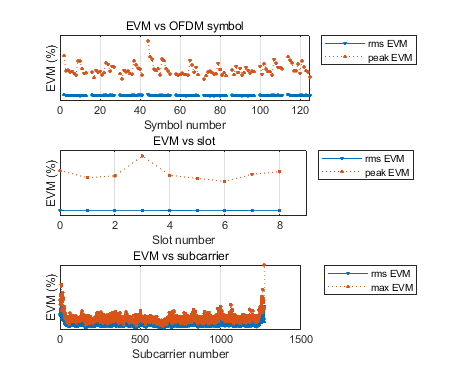

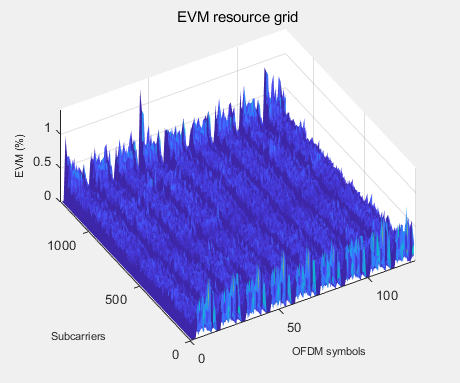

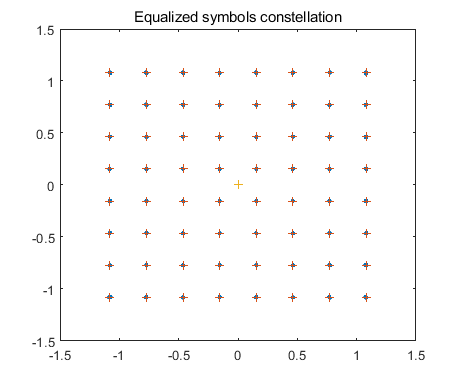

Averaged overall RMS EVM: 0.115%
Overall Peak EVM = 1.2416%


evmFilterInfo = hNRPDSCHEVM(tmWaveGen.Config,filtTmWaveform,evmCfg);